# Analyzer_voltages.mlx

## This file statistically analyzes the voltages for symptoms of Critical Slowing Down.

#### This script changes all interpretation parameters to LaTeX. Plot titles, labels, ticks, etc. will now be shown in the superior LaTeX representation instead of the generic, uninspiring regular MATLAB font.

list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

tic
folder_name = 'saved_outputs/'; %subfolder where data will be stored

system_name = 'ieee9'

system_name = 'ieee9'

run_number = 1

run_number = 1


tableName = strcat(folder_name, 'nominalValuesTable_', system_name, '_', ...
    string(run_number), '.csv')

tableName = "saved_outputs/nominalValuesTable_ieee9_1.csv"

nominalValuesTable = readtable(tableName);

busesToPlot = [1 2 3 4 5 6 7 8 9];
% busesToPlot = [3];

sampling_rate = nominalValuesTable.sampling_rate

sampling_rate = 0.0100

downsampling_ratio = nominalValuesTable.downsampling_ratio

downsampling_ratio = 1

% downsampling_ratio = 10
downsampled_rate = sampling_rate*downsampling_ratio

downsampled_rate = 0.0100

T = nominalValuesTable.T

T = 10


if T < 1
    windowInSec = strcat('point',string(10*T),'_sec');
else
    windowInSec = strcat(string(T),'_sec');
end

W = nominalValuesTable.W

W = 1000

% W = 300
W_moving = W*nominalValuesTable.window_moving_ratio;

voltsTruncatedArrName = strcat(folder_name,'voltsTruncated_', ...
    system_name, '_', string(run_number), '.mat');
voltsTruncatedArr = load(voltsTruncatedArrName);
voltsTruncatedArr = voltsTruncatedArr.voltsTruncatedArr;

#### Downsample the data if needed

voltsTruncatedArr = voltsTruncatedArr(1:downsampling_ratio:end,:);

bifurcationIdx = nominalValuesTable.bifurcationIdx

bifurcationIdx = 8438

indicesToPlotTruncated = 1:downsampling_ratio:bifurcationIdx;
indicesToPlotTruncated = ceil(indicesToPlotTruncated/downsampling_ratio)

indicesToPlotTruncated =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


xaxisTruncated = (bifurcationIdx/downsampling_ratio - indicesToPlotTruncated)...
    *sampling_rate/(60);

#### Time to smooth the voltages using Gaussian Kernel Smoothing (GKS).

sigma_f = 5;
GKS = @(n, sigma_f) (1/...
    ( sqrt(2*pi) * sigma_f ))*exp(-n^2/( 2 * (sigma_f^2) ))

GKS = function_handle with value:
    @(n,sigma_f)(1/(sqrt(2*pi)*sigma_f))*exp(-n^2/(2*(sigma_f^2)))


% syms GKS_sym(n, sigma_f)
% GKS_sym(n,sigma_f) = (1/( sqrt(2*pi) * sigma_f )) * exp(-n^2/( 2 * (sigma_f^2) ))
% var = vpa(GKS_sym)
gksFilter = [];
for n = 1:W
    gksFilter(n) = GKS(n, sigma_f);
end
gksFilter = gksFilter.*(1/sum(gksFilter));
gks_voltsTruncatedArr = [];

#### Convolve Bus Voltages with GKS filter for every bus.

% for bus = 1:size(voltsTruncatedArr,2)
% %     gks_voltsTruncatedArr(:, bus) = ...
% %         conv(voltsTruncatedArr(:, bus), gksFilter, 'same');
%     gks_voltsTruncatedArr(:, bus) = ...
%             smooth(voltsTruncatedArr(:, bus));
% end
% 
% save(strcat(folder_name,'gks_voltsTruncated_', ...
%     system_name, '.mat'),'gks_voltsTruncatedArr');
% 
% convolutionMargin = nominalValuesTable.convolutionMargin %percentage value to be truncated
% convolutionMargin = floor(bifurcationIdx*0.05) %number of samples (at sampling_rate intervals)...
% % to be truncated
% indicesToPlotPostConvolution = 1:downsampling_ratio:bifurcationIdx-W+1-convolutionMargin;
% indicesToPlotPostConvolution = ceil(indicesToPlotPostConvolution/downsampling_ratio);
% xaxisPostConvolution = (bifurcationIdx/downsampling_ratio - indicesToPlotPostConvolution)...
%     *sampling_rate/(60);
% 
% voltsTruncatedDetrendedArr = ...
%     voltsTruncatedArr(indicesToPlotPostConvolution, :) -...
%     gks_voltsTruncatedArr(indicesToPlotPostConvolution, :);
% 
% plot(xaxisPostConvolution, voltsTruncatedDetrendedArr(:, busesToPlot))
% set(gca, 'xdir', 'reverse')
% title('Detrended Voltages (pu)')
% xlabel('Time to Bifucation (min)');
% ylabel('AR1 coefficient');
% 
% save(strcat(folder_name,'voltsTruncatedDetrended_', ...
%     system_name, '.mat'),'voltsTruncatedDetrendedArr');

#### Calculate Autocorrelations and Variances

lag = 10

lag = 10

clear ar1_vector ar2_vector ar3_vector var_vector
voltsTruncatedDetrendedArr = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
smoothVoltsTruncatedArr = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
ar1_vector = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
ar2_vector = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
ar3_vector = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
var_vector = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));

convolutionMargin = 0;
for i = 1:length(busesToPlot)
    currentBus = busesToPlot(i);
    for startingSample = ...
            1:W_moving/downsampling_ratio:length(voltsTruncatedArr)-W/downsampling_ratio-lag
        if mod(startingSample, 1000) == 0
            formatSpec = 'The Bus is %4.2f, startingSample is now %4.2f\n';
            fprintf(formatSpec,currentBus, startingSample)
        end
        currentIndices1 = startingSample:startingSample+W/downsampling_ratio-1;
        indicesToPlotPostConvolution = currentIndices1;
%         smoothVoltsTruncatedArr(indicesToPlotPostConvolution, currentBus) ...
%             = smoothdata(voltsTruncatedArr(indicesToPlotPostConvolution, currentBus),...
%             'gaussian');
        smoothVoltsTruncatedArr(indicesToPlotPostConvolution, currentBus) ...
            = smooth(voltsTruncatedArr(indicesToPlotPostConvolution, currentBus));

%         smoothVoltsTruncatedArr(indicesToPlotPostConvolution, currentBus) = ...
%             conv(voltsTruncatedArr(indicesToPlotPostConvolution, currentBus), gksFilter, 'same');
%         voltsTruncatedDetrendedArr = ...
%             voltsTruncatedArr(indicesToPlotPostConvolution, currentBus) -...
%             smooth(voltsTruncatedArr(indicesToPlotPostConvolution, currentBus));
        voltsTruncatedDetrendedArr(indicesToPlotPostConvolution, currentBus) = ...
            voltsTruncatedArr(indicesToPlotPostConvolution, currentBus) -...
            smoothVoltsTruncatedArr(indicesToPlotPostConvolution, currentBus);
%         sys = ar(voltsTruncatedDetrendedArr...
%             (currentIndices1, currentBus), ...
%             1, 'ls');
        sys = ar(voltsTruncatedDetrendedArr(indicesToPlotPostConvolution, currentBus), lag, 'ls');
        [num,den] = tfdata(sys,'v');
%         a1 = den(2);
%         a1 = -1/den(2);
        a1 = abs(den(2));
%         mu = mean(...
%             voltsTruncatedDetrendedArr(...
%             currentIndices1, currentBus));
%         firstArray = ...
%             voltsTruncatedDetrendedArr(currentIndices1, currentBus)...
%             - mu;
%         
%         secondArray = ...
%             voltsTruncatedDetrendedArr([currentIndices1]+lag, currentBus)...
%             - mu;
%         a3 = sum(firstArray.*secondArray)/sum(firstArray.*firstArray);
%         acf = autocorr(...
%             voltsTruncatedDetrendedArr(currentIndices1,...
%             currentBus),...
%             numLags = lag);
%         a2 = acf(lag);
        ar1_vector(startingSample, currentBus) = a1;
%         ar2_vector(startingSample, i) = a2;
%         ar3_vector(startingSample, i) = a3;
%         sigma_squared = ...
%             var(voltsTruncatedDetrendedArr(...
%             currentIndices1, i));
        sigma_squared = ...
            var(voltsTruncatedDetrendedArr(indicesToPlotPostConvolution, currentBus));
        var_vector(startingSample, currentBus) = sigma_squared;

    end
end

smoothVoltsTruncatedArrName = strcat(folder_name,'smoothVoltsTruncated_', ...
            system_name, '_', string(run_number), '_T_', windowInSec, '_lag_',...
            string(lag), '.mat')

smoothVoltsTruncatedArrName = "saved_outputs/smoothVoltsTruncated_ieee9_1_T_10_sec_lag_10.mat"


save(smoothVoltsTruncatedArrName, 'smoothVoltsTruncatedArr');

voltsTruncatedDetrendedArrName = strcat(folder_name,'voltsTruncatedDetrended_', ...
            system_name, '_', string(run_number), '_T_', windowInSec, '_lag_',...
            string(lag), '.mat')

voltsTruncatedDetrendedArrName = "saved_outputs/voltsTruncatedDetrended_ieee9_1_T_10_sec_lag_10.mat"


save(voltsTruncatedDetrendedArrName, 'voltsTruncatedDetrendedArr');

indicesToPlotPostParametrization = 1:downsampling_ratio:length(voltsTruncatedArr)-W/downsampling_ratio-convolutionMargin-lag;
indicesToPlotPostParametrization = ceil(indicesToPlotPostParametrization/downsampling_ratio);
xaxisPostParametrization = (bifurcationIdx/downsampling_ratio - indicesToPlotPostParametrization)...
    *sampling_rate/(60);

plot(xaxisPostParametrization, ar1_vector(:, busesToPlot))
set(gca, 'xdir', 'reverse')
title('AR1 coefficients via $\tt{ar}$ function in MATLAB')
xlabel('Time to Bifucation (min)');
ylabel('AR1 coefficient');

#### Plot and save the autocorrelation graphs.

pdf_location_name = 'pdf/';

imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number), ...
    '_ar1_MATLAB_ar_function','_T_', windowInSec, '_lag_', string(lag))

imagePdfName = "pdf/ieee9_1_ar1_MATLAB_ar_function_T_10_sec_lag_10"

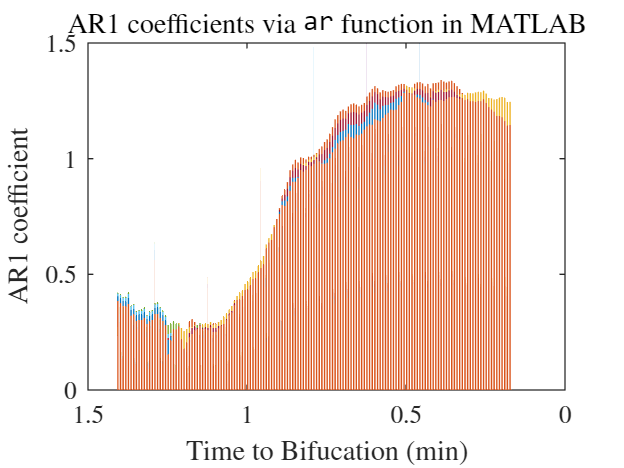

set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it


% plot(xaxisPostParametrization, ar2_vector(:, 3))
% set(gca, 'xdir', 'reverse')
% title('lag $\tau=1$ coefficients via $\tt{autocorr}$ function in MATLAB')
% xlabel('Time to Bifucation (min)');
% ylabel('AR1 coefficient');
% imagePdfName = strcat(pdf_location_name, system_name,...
%     '_ar1_MATLAB_autocorr_function','_T_',windowInSec)
% set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
% % print(imagePdfName,'-dpdf', '-fillpage') % then print it

% plot(xaxisPostParametrization, ar3_vector(:, 3))
% set(gca, 'xdir', 'reverse')
% title('lag $\tau=1$ coefficients via manual implementation of autocorrelation')
% xlabel('Time to Bifucation (min)');
% ylabel('AR1 coefficient');
% imagePdfName = strcat(pdf_location_name, system_name,...
%     '_ar1_manual_implementation','_T_',windowInSec)
% set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
% % print(imagePdfName,'-dpdf', '-fillpage') % then print it

plot(xaxisPostParametrization, var_vector(:, busesToPlot))
set(gca, 'xdir', 'reverse')
title('Variance values via $\tt{var}$ function in MATLAB.')
xlabel('Time to Bifucation (min)');
ylabel('$\sigma^2$ coefficient');
imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number),...
    '_var_manual_implementation','_T_',windowInSec, '_lag_', string(lag))

imagePdfName = "pdf/ieee9_1_var_manual_implementation_T_10_sec_lag_10"

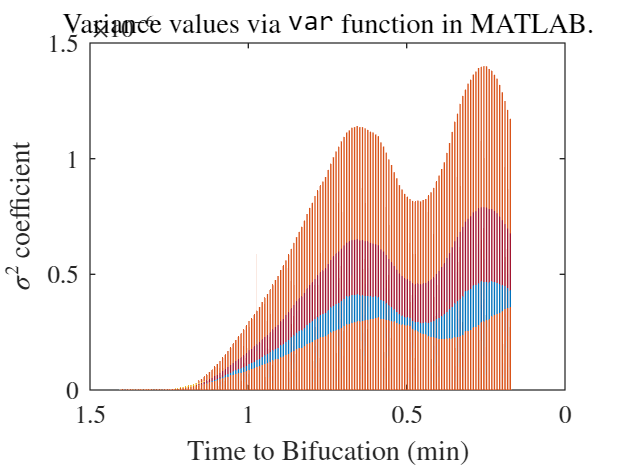

set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it



ar1VoltagesName = strcat(folder_name,'ar1_vector_bus_voltages_', ...
    system_name, '_', string(run_number), num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

ar1VoltagesName = "saved_outputs/ar1_vector_bus_voltages_ieee9_110_sec_lag_10.mat"

save(ar1VoltagesName,  'ar1_vector');

varVoltagesName = strcat(folder_name,'var_vector_bus_voltages_', ...
    system_name,  '_', string(run_number), num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

varVoltagesName = "saved_outputs/var_vector_bus_voltages_ieee9_110_sec_lag_10.mat"

save(varVoltagesName, 'var_vector');

toc

Elapsed time is 26.049782 seconds.
